clc, clear
t = [0, 1, 2, 2.5, 3, 3.5, 4, 4.5, 5, 5.5, 6, 7, 8];
x = [0, 4.1, 14.9, 25.4, 37.5, 48.4, 59, 69.6, 80.3, 92.2, 103.5, 115.3, 119.8];
y = [31.6, 22.3, 7.1, 2, 3.54, 7.6, 10, 8.2, 4.3, 1.8, 5.7, 21.2, 31.1];

% syms x x1 x2 x3 x4
% eq = (x-x2)*(x-x3)*(x-x4)
% eq = expand(eq)
% d = diff(eq)
% dd = diff(d)

[xd, xdd] = PySDerDes(t, x);
[yd, ydd] = PySDerDes(t, y);
v = sqrt(xd.^2+yd.^2);
a = sqrt(xdd.^2+ydd.^2);

res = table( ...
    num2str(t', '%.2f'), ...
    num2str(x', '%.2f'), ...
    num2str(y', '%.2f'),...
    num2str(v', '%.4f'), ...
    num2str(a', '%.4f'), ...
    VariableNames={'t(s)', 'x(m)', 'y(m)', 'v(m/s)', 'a(m/s²)'});
disp(res)

    t(s)     x(m)     y(m)      v(m/s)     a(m/s²) 
    ____    ______    _____    ________    ________

    0.00      0.00    31.60      8.4537     26.5391
    1.00      4.10    22.30     15.5520     15.5520
    2.00     14.90     7.10      7.9961      7.9961
    2.50     25.40     2.00     45.8017     45.8017
    3.00     37.50     3.54     66.8000     66.8000
    3.50     48.40     7.60     80.7716     80.7716
    4.00     59.00    10.00    101.5074    101.5074
    4.50     69.60     8.20    101.8945    101.8945
    5.00     80.30     4.30     95.0303     95.0303
    5.50     92.20     1.80    138.9539    138.9539
    6.00    103.50     5.70    146.2935    146.2935
    7.00    115.30    21.20    127.5982    165.1292
    8.00    119.80    31.10    135.7568    198.6945





% Límites del dibujo
l1_x = min(x); l2_x = max(x);
xx = linspace(l1_x, l2_x)

xx =          0    1.2101    2.4202    3.6303    4.8404    6.0505    7.2606    8.4707    9.6808   10.8909   12.1010   13.3111   14.5212   15.7313   16.9414   18.1515   19.3616   20.5717   21.7818   22.9919   24.2020   25.4121   26.6222   27.8323   29.0424   30.2525   31.4626   32.6727   33.8828   35.0929   36.3030   37.5131   38.7232   39.9333   41.1434   42.3535   43.5636   44.7737   45.9838   47.1939   48.4040   49.6141   50.8242   52.0343   53.2444   54.4545   55.6646   56.8747   58.0848   59.2949


l1_t = min(t); l2_t = max(t);
tt = linspace(l1_t, l2_t)

tt =          0    0.0808    0.1616    0.2424    0.3232    0.4040    0.4848    0.5657    0.6465    0.7273    0.8081    0.8889    0.9697    1.0505    1.1313    1.2121    1.2929    1.3737    1.4545    1.5354    1.6162    1.6970    1.7778    1.8586    1.9394    2.0202    2.1010    2.1818    2.2626    2.3434    2.4242    2.5051    2.5859    2.6667    2.7475    2.8283    2.9091    2.9899    3.0707    3.1515    3.2323    3.3131    3.3939    3.4747    3.5556    3.6364    3.7172    3.7980    3.8788    3.9596



% Dibujo
subplot(3, 1, 1)
plot(x, y,'b.', MarkerSize=12);
pp = spline(x, y)

pp = struct with fields:
      form: 'pp'
    breaks: [0 4.1000 14.9000 25.4000 37.5000 48.4000 59 69.6000 80.3000 92.2000 103.5000 115.3000 119.8000]
     coefs: [12×4 double]
    pieces: 12
     order: 4
       dim: 1


yy = ppval(pp, xx);
hold on
plot(xx, yy, 'b-')
title('Posición m')
xlabel('x'); ylabel('y')
hold off

subplot(3, 1, 2)
plot(t, v, 'r.', MarkerSize=12)
pp = spline(t, v)

pp = struct with fields:
      form: 'pp'
    breaks: [0 1 2 2.5000 3 3.5000 4 4.5000 5 5.5000 6 7 8]
     coefs: [12×4 double]
    pieces: 12
     order: 4
       dim: 1


yy = ppval(pp, tt);
hold on
plot(tt, yy, 'r-')
title('Velocidad m/s')
xlabel('t'); ylabel('v(t)', Rotation=90)
hold off

subplot(3, 1, 3)
plot(t, a, 'm.', MarkerSize=12)
pp = spline(t, a)

pp = struct with fields:
      form: 'pp'
    breaks: [0 1 2 2.5000 3 3.5000 4 4.5000 5 5.5000 6 7 8]
     coefs: [12×4 double]
    pieces: 12
     order: 4
       dim: 1


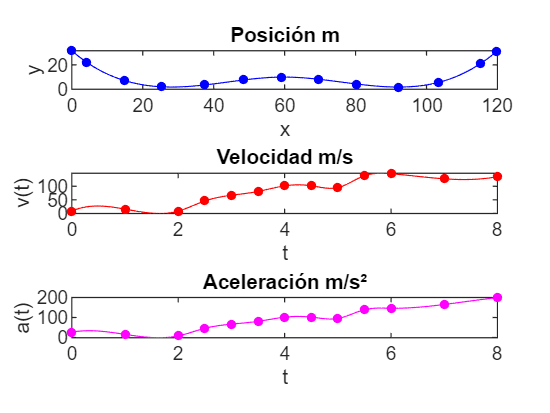

yy = ppval(pp, tt);
hold on
plot(tt, yy, 'm-')
title('Aceleración m/s²')
xlabel('t'); ylabel('a(t)')
hold off